# 1 一维傅里叶变换

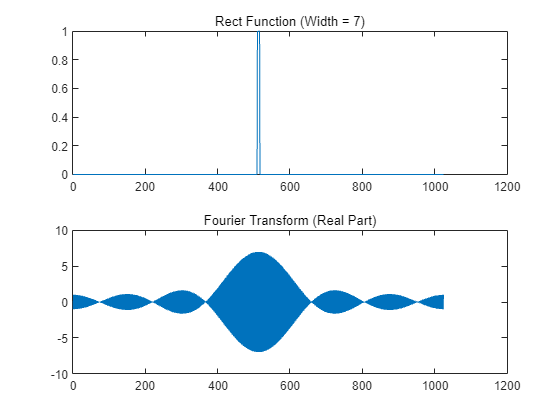

% i Create the Sequence and Apply the Rect Function:
sequence = zeros(1, 1024);
width = 7;
start_index = 513 - floor(width / 2);
end_index = start_index + width - 1;
sequence(start_index:end_index) = 1;
%Fourier Transform and Plotting:
% Fourier Transform
fft_sequence = fftshift(fft(sequence));

% Plotting
subplot(2,1,1);
plot(sequence);
title('Rect Function (Width = 7)');
subplot(2,1,2);
plot(real(fft_sequence));
title('Fourier Transform (Real Part)');

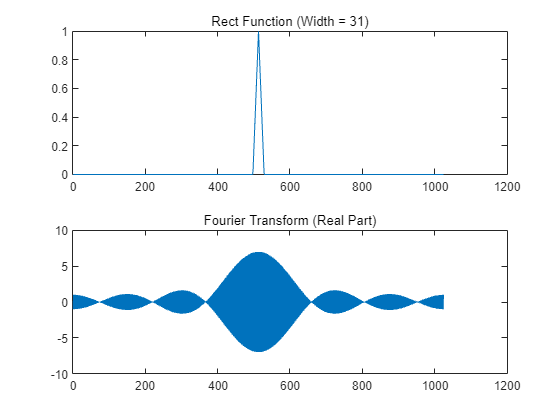

% vi Create the Triangle Function
width = 31; % Repeat for 15 and 31
midpoint = 513;
start_index = midpoint - floor(width / 2);
end_index = start_index + width - 1;
peak = 1;
slope = peak / (width / 2);
for i = start_index:end_index
    distance_from_midpoint = abs(midpoint - i);
    sequence(i) = peak - slope * distance_from_midpoint;
end
figure;
subplot(2,1,1);
plot(sequence);
title('Rect Function (Width = 31)');
subplot(2,1,2);
plot(real(fft_sequence));
title('Fourier Transform (Real Part)');

## Problem 2 - 2-D transforms

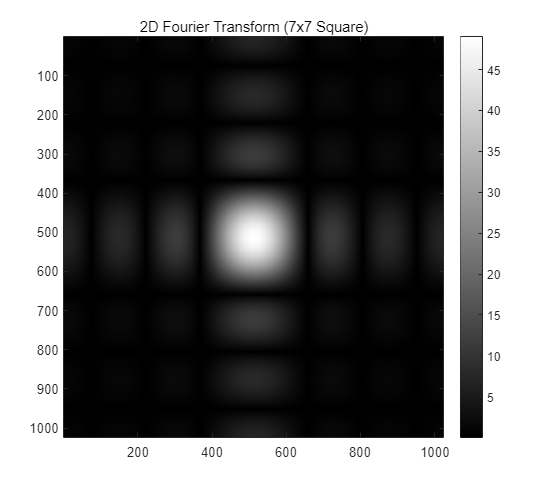

% i square array 7 7 
A = zeros(1024, 1024);
center = [513, 513];
width = 7;
half_width = floor(width / 2);
A(center(1)-half_width:center(1)+half_width, center(2)-half_width:center(2)+half_width) = 1;

B = fftshift(fft2(A));
imagesc(abs(B)); % Image of the absolute value
title('2D Fourier Transform (7x7 Square)');
colormap('gray'); % For better visualization
colorbar;

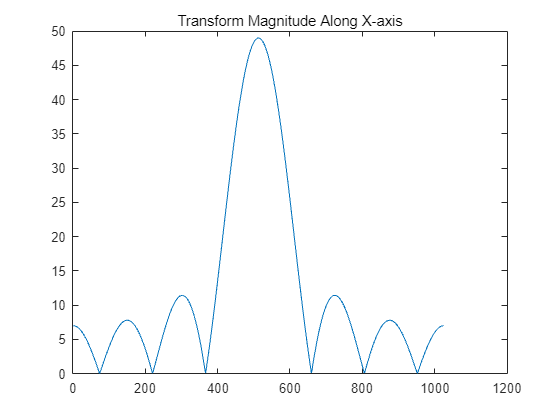


% Plotting a cut along one of the coordinate axes
figure;
plot(abs(B(513, :)));
title('Transform Magnitude Along X-axis');

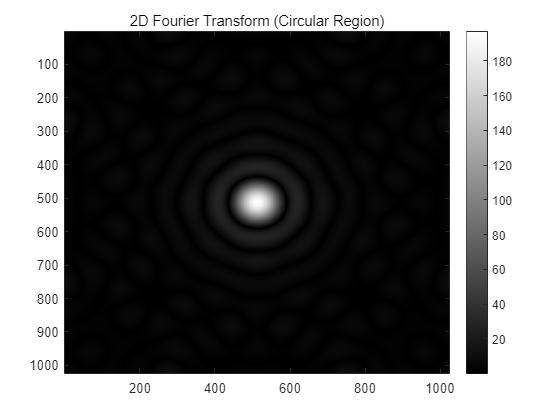

%iii: Circular Region (Diameter 16)
A = zeros(1024, 1024);
[X, Y] = meshgrid(1:1024, 1:1024);
radius = 8; % Half of the diameter
circle = sqrt((X - center(1)).^2 + (Y - center(2)).^2) <= radius;
A(circle) = 1;

B = fftshift(fft2(A));
imagesc(abs(B)); % Image of the absolute value
title('2D Fourier Transform (Circular Region)');
colormap('gray'); % For better visualization
colorbar;

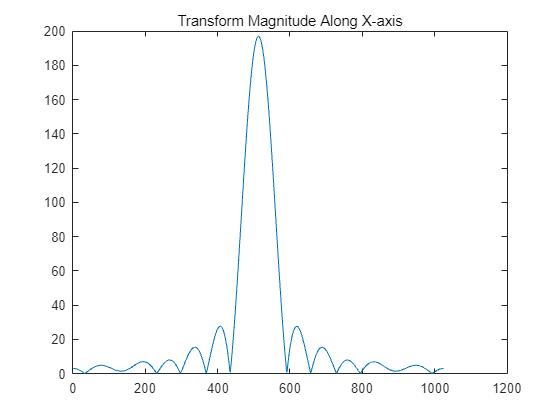


% Plotting a cut along one of the coordinate axes
figure;
plot(abs(B(513, :)));
title('Transform Magnitude Along X-axis');

## Problem 3 - A low-pass filter.

filename = 'C:\\Users\\HP\\Desktop\\上课\\图像处理代码\\lab7\\For Students\\lab7prob3data'; 

% Reading the image using imread
fileID = fopen(filename, 'rb'); 
imagea = fread(fileID, [512, 512], 'uint8'); 
% Verify that the image is 512x512. If not, you'll need to resize or adjust the code accordingly.

% Computing the Fourier Transform
fft_image = fftshift(fft2(imagea));

% Creating and applying the mask
mask_width = 255; % For mask width 127, change this to 127
mask = zeros(512, 512);
center = [256, 256];
mask(center(1)-mask_width/2:center(1)+mask_width/2, center(2)-mask_width/2:center(2)+mask_width/2) = 1;

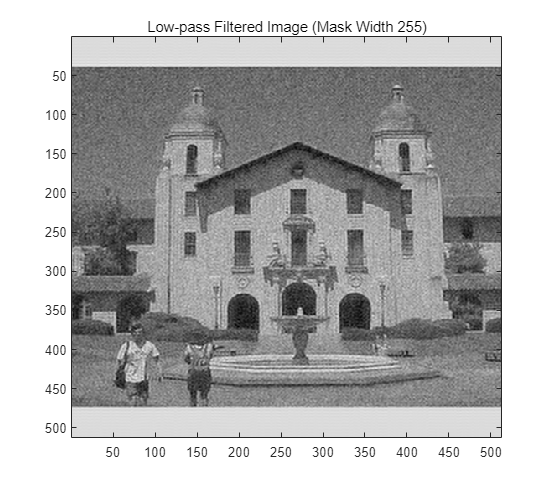

filtered_fft = fft_image .* mask;

% Inverse FFT and displaying the image
filtered_image = ifft2(ifftshift(filtered_fft));
imagesc(abs(filtered_image'));
colormap('gray');
title('Low-pass Filtered Image (Mask Width 255)');

## Problem 4 – Sharpening a blurred image.

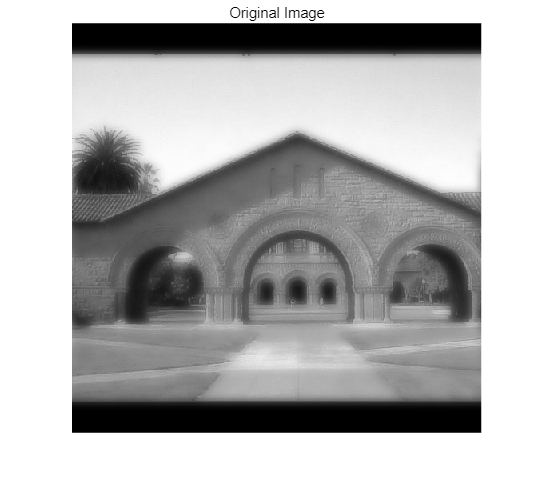

filename = 'C:\\Users\\HP\\Desktop\\上课\\图像处理代码\\lab7\\For Students\\lab7prob4data'; 
% Reading the image using imread
fileID = fopen(filename, 'rb'); 
image4 = fread(fileID, [512, 512], 'uint8'); 

% 显示原始图像
normalized_image = mat2gray(image4);
imshow(normalized_image');
title('Original Image');

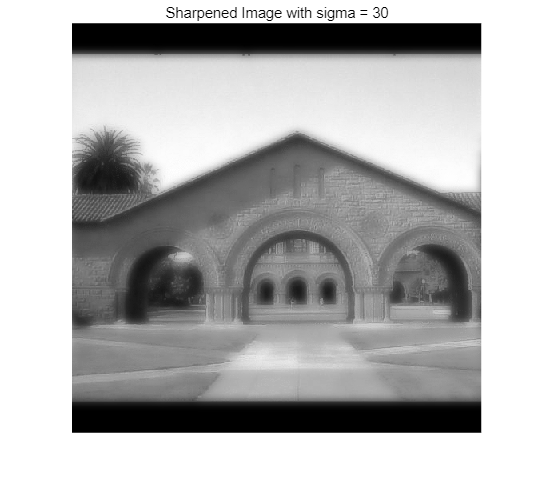


% 定义sigma的值和q的范围
sigma_values = [5, 10, 20, 30, 40, 50];
q_range = -256:255;

% 对图像进行傅里叶变换
F_image = fft2(image4);

% 创建meshgrid以生成二维频域滤波器
[U, V] = meshgrid(q_range, q_range);
q = sqrt(U.^2 + V.^2);

% 选择一个sigma值并应用滤波器
sigma = 30; % 可以尝试不同的sigma值
g_q = exp(-q.^2 / (2 * sigma^2)) / (sigma * sqrt(pi)) * 0.99 + 0.01;
filtered_F_image = F_image ./ g_q;

% 进行反傅里叶变换以获取锐化后的图像
sharpened_image = ifft2(filtered_F_image);

% 显示锐化后的图像
figure;
normalized_image_1 = mat2gray(sharpened_image);
imshow(normalized_image_1');
title(['Sharpened Image with sigma = ' num2str(sigma)]);

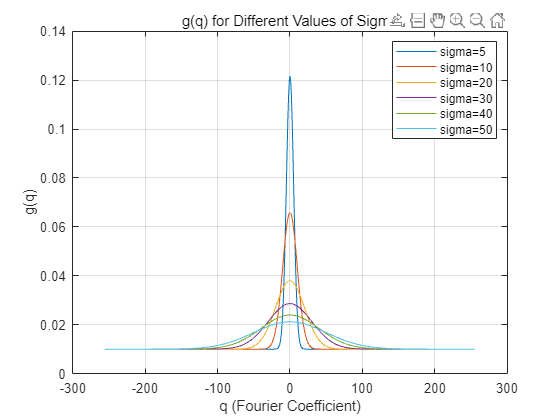


% 定义sigma的值
sigma_values = [5, 10, 20, 30, 40, 50];
% 定义q的范围
q_range = -256:255;

% 创建一个新的图形窗口
figure;

% 遍历sigma的值，为每个值绘制g(q)
for sigma = sigma_values
    q = q_range;
    g_q = exp(-q.^2 / (2 * sigma^2)) / (sigma * sqrt(pi)) * 0.99 + 0.01;
    plot(q, g_q, 'DisplayName', ['sigma=' num2str(sigma)]);
    hold on;
end

% 添加图表标题和坐标轴标签
title('g(q) for Different Values of Sigma');
xlabel('q (Fourier Coefficient)');
ylabel('g(q)');

% 显示图例
legend;
% 开启网格
grid on;

% 显示图形
hold off;

## Problem 5 – Image Manipulation in the Frequency Domain

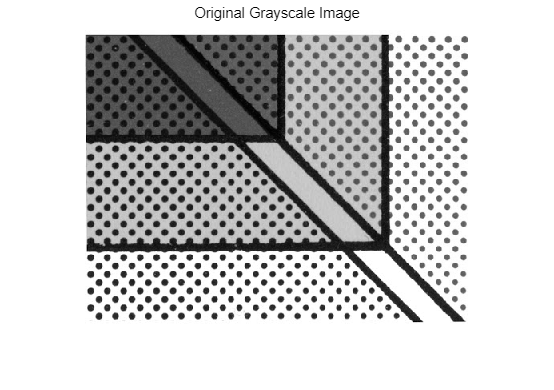

% i. 读取、转换为灰度并显示图像
image = imread('lab7prob5data.jpg');
gray_image = rgb2gray(image);
figure, imshow(gray_image), title('Original Grayscale Image');

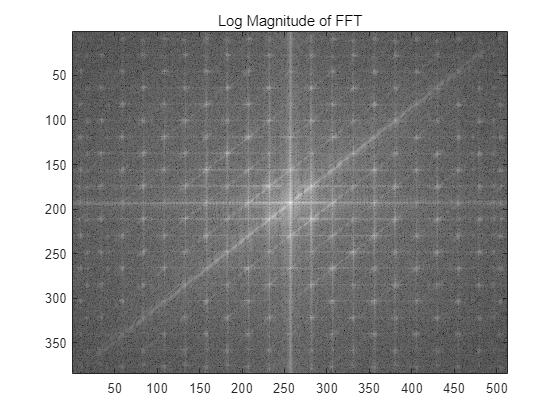


% ii. 对图像进行2D FFT并显示对数幅度
F_image = fft2(gray_image);
F_image_shifted = fftshift(F_image); % 需要移位以中心化低频部分
log_magnitude = log(abs(F_image_shifted) + 1); % 使用log(abs(img) + 1)以避免对数为负
figure, imagesc(log_magnitude), colormap gray, title('Log Magnitude of FFT');

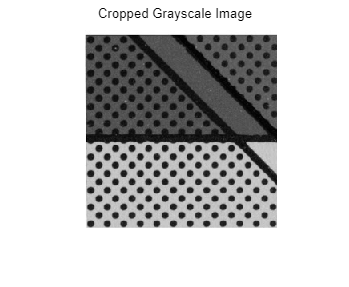


% iii. 读取、转换为灰度、裁剪并显示另一张图像
% 这里用 image 变量代表你选择的图像
gray_image2 = rgb2gray(image); 
gray_image2_cropped = gray_image2(1:256, 1:256); % 裁剪为2的幂次大小
figure, imshow(gray_image2_cropped), title('Cropped Grayscale Image');

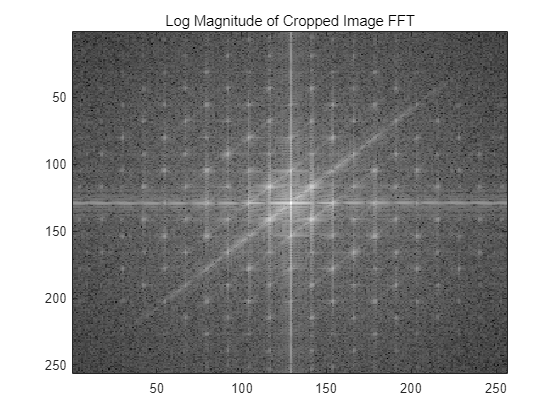


% 对裁剪后的图像进行2D FFT并显示对数幅度
F_image2 = fft2(gray_image2_cropped);
F_image2_shifted = fftshift(F_image2);
log_magnitude2 = log(abs(F_image2_shifted) + 1);
figure, imagesc(log_magnitude2), colormap gray, title('Log Magnitude of Cropped Image FFT');

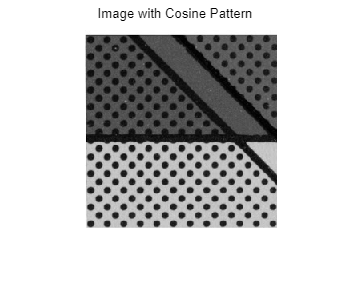


% iv. 在频域中添加2D余弦模式
F_image2_shifted(128, 128) = F_image2_shifted(128, 128) + 500; % 修改一个像素来添加模式
new_image = ifft2(ifftshift(F_image2_shifted)); % 反FFT
figure, imshow(abs(new_image), []), title('Image with Cosine Pattern');

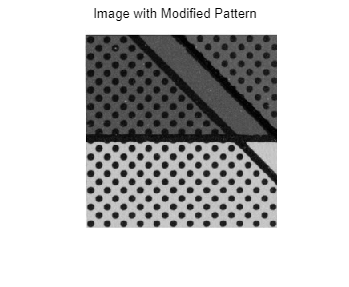


% v. 进一步修改以创建新模式
F_image2_shifted(130, 130) = F_image2_shifted(130, 130) + 500; % 添加另一个修改
new_image2 = ifft2(ifftshift(F_image2_shifted)); % 反FFT
figure, imshow(abs(new_image2), []), title('Image with Modified Pattern');